## Notch Filter implementation of the ECG signal filter

#### Import signal and plot the first second

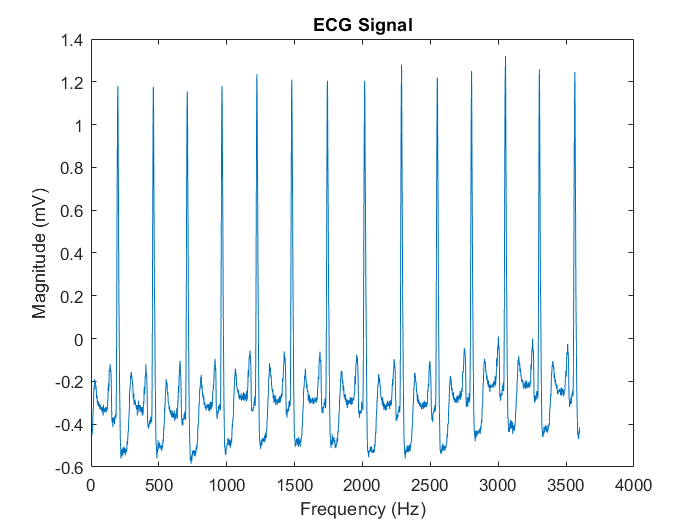

[sig, Fs, tm] = rdsamp('mitdb/105', 1);
signal = sig(1:3600);
plot(signal);
title('ECG Signal')
xlabel('Frequency (Hz)')
ylabel('Magnitude (mV)')

#### **Obtain Fourier Transform**

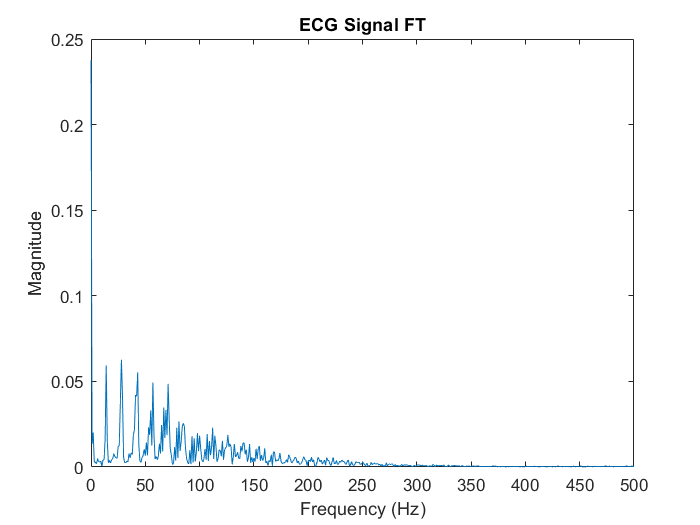

N = length(signal);     
T = 1/Fs;
sig_fft = fft(signal);
sig_fft_magnitude = abs(fftshift(sig_fft)) / N;    % Magnitude of the FFT
frequencies = (-N/2:N/2-1);      % Frequency axis

figure
plot(frequencies, sig_fft_magnitude);
title('ECG Signal FT')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
xlim([0,500])

Generate noise signal

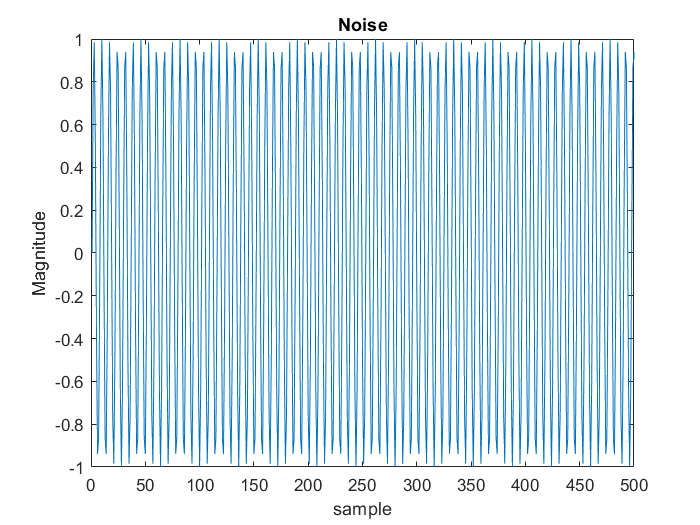

noise_t = linspace(0, (N-1)*T, N);      % Time vector
noise = sin(2 * pi * 50 * noise_t);     % 50 Hz sine wave noise
figure
plot(noise)
xlabel('sample')
ylabel('Magnitude')
title('Noise')
xlim([0,500])

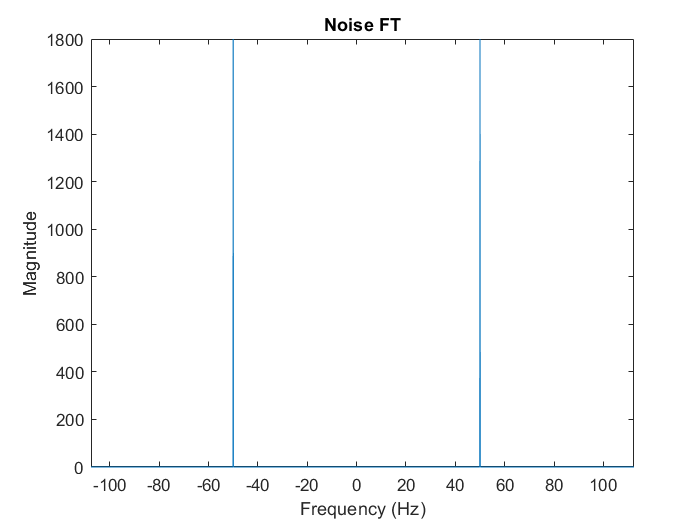


noisy_signal = signal + transpose(noise);
L = length(noisy_signal);
f = (-L/2:L/2-1) * (Fs / L);    
% Compute the FFT
Y_noise = fft(noise);
Y_noise_shifted = fftshift(abs(Y_noise));
figure
plot(f, Y_noise_shifted);
title('Noise FT')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
xlim([-100,100])

Add noise to the original signal

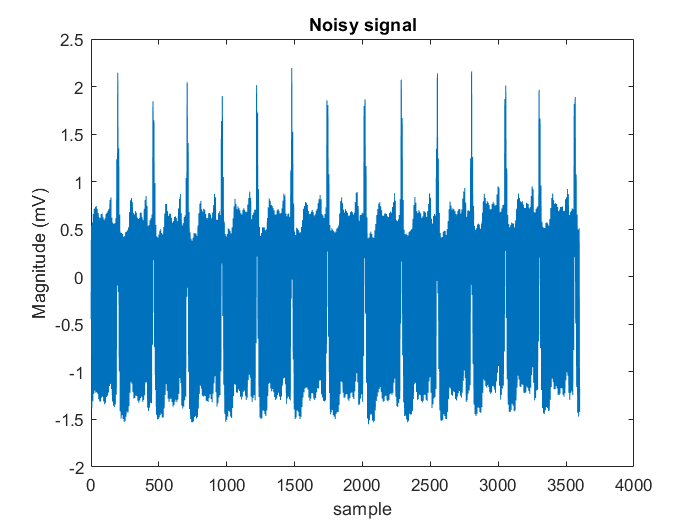


figure
plot(noisy_signal)
xlabel('sample')
ylabel('Magnitude (mV)')
title('Noisy signal')

Find FFT of noisy signal

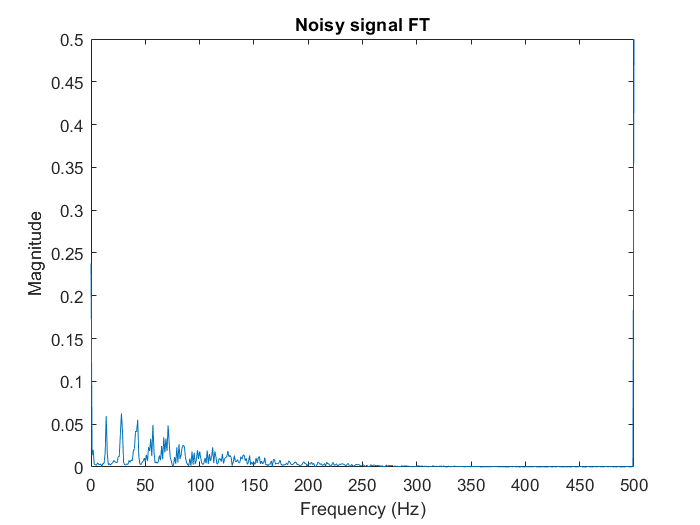

noisy_signal_fft = fft(noisy_signal);               % Perform the FFT
noisy_signal_fft_magnitude = abs(fftshift(noisy_signal_fft)) / N;    % Magnitude of the FFT
figure
plot(frequencies, noisy_signal_fft_magnitude);
title('Noisy signal FT')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
xlim([0,500])

### Notch filter

t = (0:N-1) * T;
F0 = 50; % Frequency to remove
Q = 35;  % Quality factor (controls bandwidth)

% Design the Notch Filter
wo = F0/(Fs/2);     % Normalized Frequency (0 to 1)
bw = wo/Q;          % Bandwidth

[b, a] = iirnotch(wo, bw); % Design the Notch Filter

% Frequency Response
%fvtool(b, a); % Visualize the filter

apply filter

e_notch = filtfilt(b, a, noisy_signal);

compare with original signal in time domain:

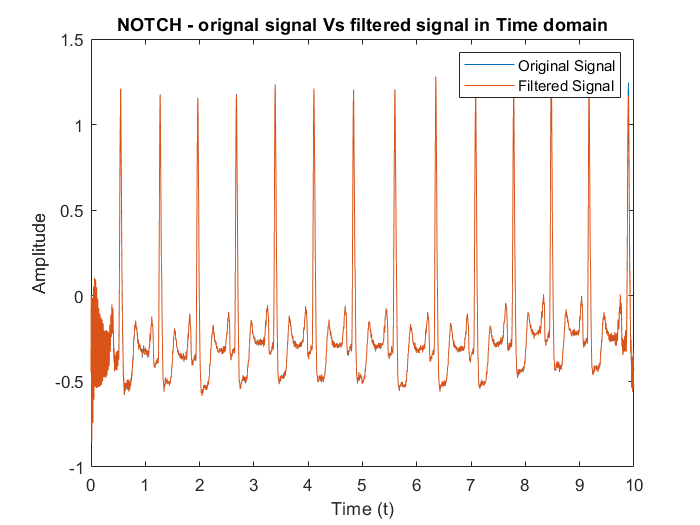

figure;
plot(t, [signal, e_notch]);
title("NOTCH - orignal signal Vs filtered signal in Time domain")
legend('Original Signal',  'Filtered Signal');
xlabel('Time (t)');
ylabel('Amplitude');

now repeat comparison in frequency domain

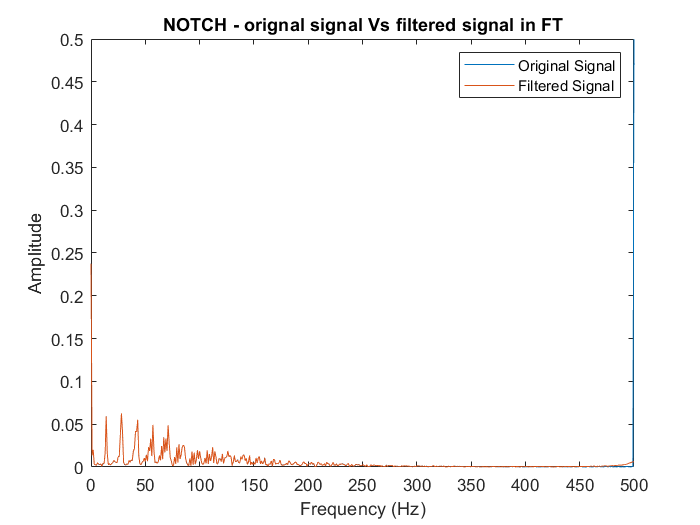

notch_fft = fft(e_notch);               % Perform the FFT
notch_fft_magnitude = abs(fftshift(notch_fft)) / N; 

figure;
plot(frequencies, [noisy_signal_fft_magnitude, notch_fft_magnitude]);
title("NOTCH - orignal signal Vs filtered signal in FT")
legend('Original Signal',  'Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0,500])


notch_SNR = calculate_SNR(signal, e_notch);
notch_PRD = calculate_PRD(signal, e_notch);
notch_MSE = calculate_MSE(signal, e_notch);
disp(['notch_SNR = ', num2str(notch_SNR)]);

notch_SNR = -20.4655


disp(['notch_PDR = ', num2str(notch_PRD)]);

notch_PDR = 9.4782


disp(['notch_MSE = ', num2str(notch_MSE)]);

notch_MSE = 0.001323


### LMS implementation

The following fields will be used by all adaptive filters

mu = 0.01; % Learning rate (step size)
filter_len = 32; % Filter length
delay = 8; % Delay in samples, roughly corresponding to one period of 50Hz noise at Fs=360Hz
reference_signal = transpose(noise);%[zeros(delay, 1); noisy_signal(1:end-delay)];

Lms Implementation:

lms = dsp.LMSFilter('Length', filter_len, 'StepSize', mu, 'Method', 'LMS');
[y_lms, e_lms] = lms(reference_signal, noisy_signal);

compare with original signal in time domain:

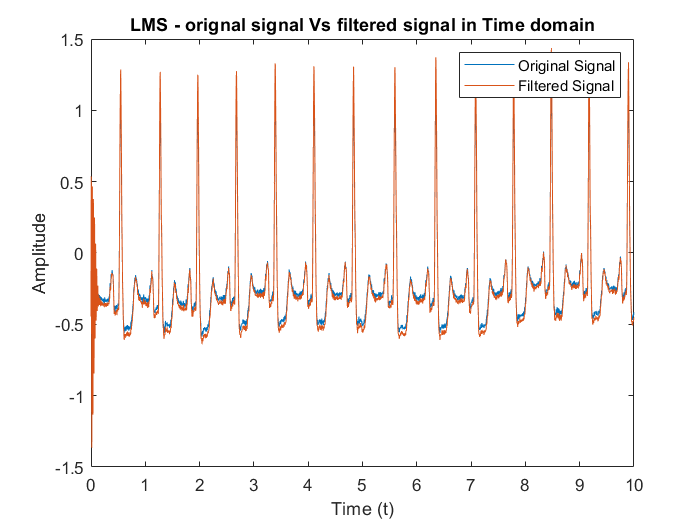

figure;
plot(t, [signal, e_lms]);
title("LMS - orignal signal Vs filtered signal in Time domain")
legend('Original Signal',  'Filtered Signal');
xlabel('Time (t)');
ylabel('Amplitude');

now repeat comparison in frequency domain

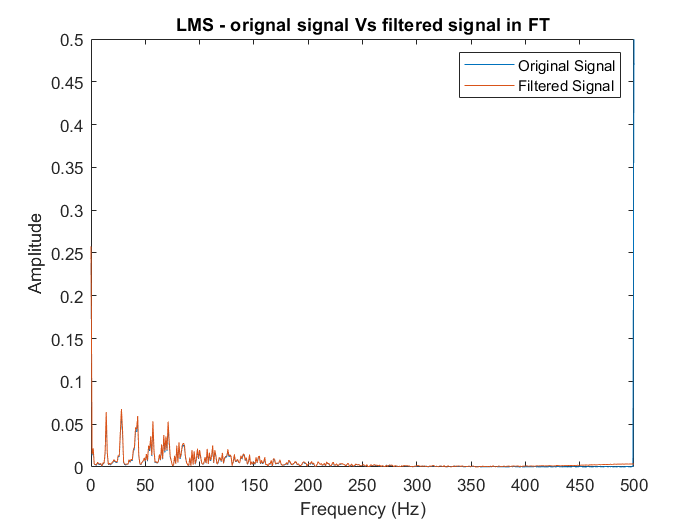

lms_fft = fft(e_lms);               % Perform the FFT
lms_fft_magnitude = abs(fftshift(lms_fft)) / N; 

figure;
plot(frequencies, [noisy_signal_fft_magnitude, lms_fft_magnitude]);
title("LMS - orignal signal Vs filtered signal in FT")
legend('Original Signal',  'Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0,500])

Calculate statistics

lms_SNR = calculate_SNR(signal, e_lms);
lms_PRD = calculate_PRD(signal, e_lms);
lms_MSE= calculate_MSE(signal, e_lms);

disp(['lms_SNR = ',num2str(lms_SNR)]);

lms_SNR = -15.9972


disp(['lms_PRD = ',num2str(lms_PRD)]);

lms_PRD = 15.854


disp(['lms_MSE = ',num2str(lms_MSE)]);

lms_MSE = 0.0037015


### Normalized LMS implementation

n_lms = dsp.LMSFilter('Length', filter_len, 'StepSize', mu, 'Method', 'Normalized LMS');
[y_nlms, e_nlms] = n_lms(reference_signal, noisy_signal);

compare with original signal in time domain:

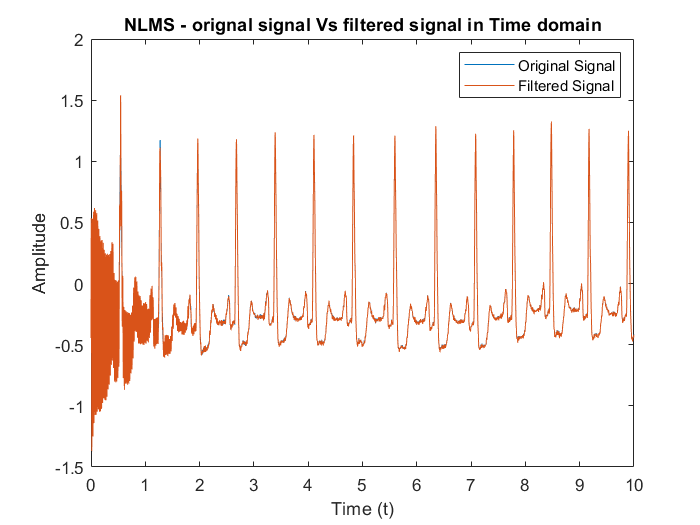

figure;
plot(t, [signal, e_nlms]);
title("NLMS - orignal signal Vs filtered signal in Time domain")
legend('Original Signal',  'Filtered Signal');
xlabel('Time (t)');
ylabel('Amplitude');

now repeat comparison in frequency domain

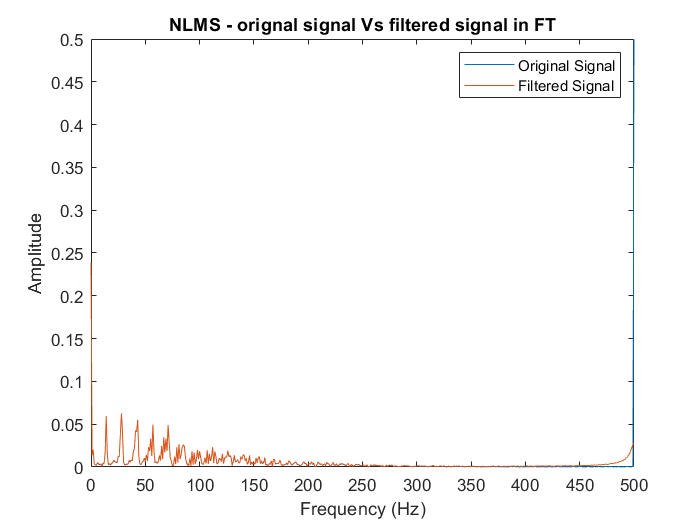

nlms_fft = fft(e_nlms);               % Perform the FFT
nlms_fft_magnitude = abs(fftshift(nlms_fft)) / N; 

figure;
plot(frequencies, [noisy_signal_fft_magnitude, nlms_fft_magnitude]);
title("NLMS - orignal signal Vs filtered signal in FT")
legend('Original Signal',  'Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0,500])

calculate statistics

nlms_SNR = calculate_SNR(signal, e_nlms);
nlms_PRD = calculate_PRD(signal, e_nlms);
nlms_MSE= calculate_MSE(signal, e_nlms);

disp(['lms_SNR = ',num2str(nlms_SNR)]);

lms_SNR = -10.1997


disp(['lms_PRD = ',num2str(nlms_PRD)]);

lms_PRD = 30.9038


disp(['lms_MSE = ',num2str(nlms_MSE)]);

lms_MSE = 0.014065


### RLS implementation

lambda = 0.999; % Forgetting factor
rls = dsp.RLSFilter('Length',filter_len,'ForgettingFactor',lambda);
[y_rls, e_rls] = rls(reference_signal, noisy_signal);

compare with original signal in time domain:

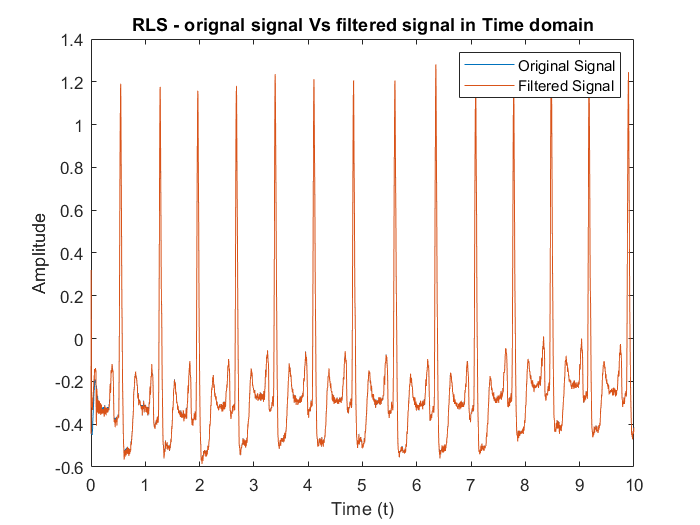

figure;
plot(t, [signal, e_rls]);
title("RLS - orignal signal Vs filtered signal in Time domain")
legend('Original Signal',  'Filtered Signal');
xlabel('Time (t)');
ylabel('Amplitude');

compare with original signal in frequency domain:

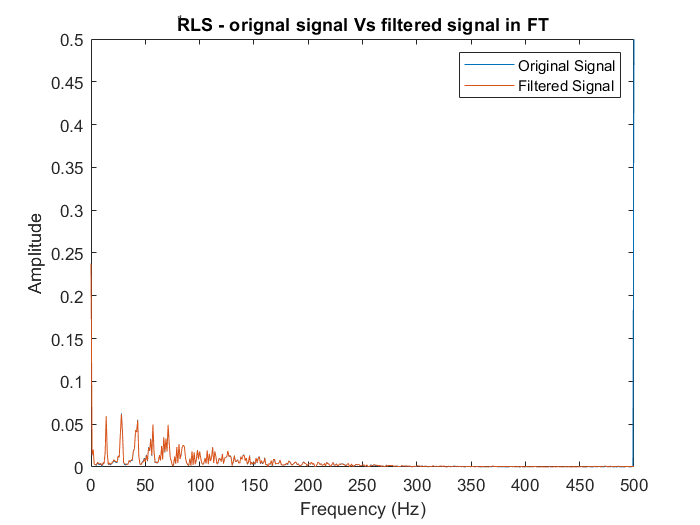

rls_fft = fft(e_rls);               % Perform the FFT
rls_fft_magnitude = abs(fftshift(rls_fft)) / N; 

figure;
plot(frequencies, [noisy_signal_fft_magnitude, rls_fft_magnitude]);
title("ٌRLS - orignal signal Vs filtered signal in FT")
legend('Original Signal',  'Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0,500])

calculate statistics

rls_SNR = calculate_SNR(signal, e_rls);
rls_PRD = calculate_PRD(signal, e_rls);
rls_MSE = calculate_MSE(signal, e_rls);
disp(['rls_SNR = ', num2str(rls_SNR)]);

rls_SNR = -26.2435


disp(['rls_PDR = ', num2str(rls_PRD)]);

rls_PDR = 4.8733


disp(['rls_MSE = ', num2str(rls_MSE)]);

rls_MSE = 0.00034975


### Affine Projection Filter (APA)

apa = dsp.AffineProjectionFilter('Length',filter_len,'StepSize',mu,'ProjectionOrder', 4);
[y_apa, e_apa] = apa(reference_signal, noisy_signal);

compare with original signal in time domain:

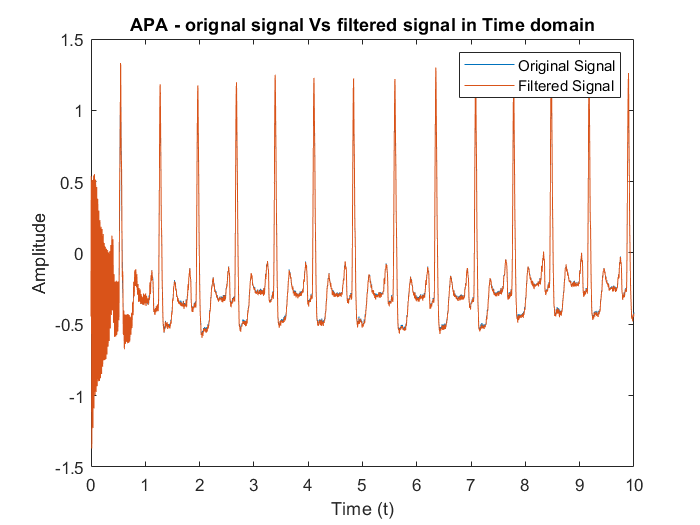

figure;
plot(t, [signal, e_apa]);
title("APA - orignal signal Vs filtered signal in Time domain")
legend('Original Signal',  'Filtered Signal');
xlabel('Time (t)');
ylabel('Amplitude');

compare with original signal in frequency domain:

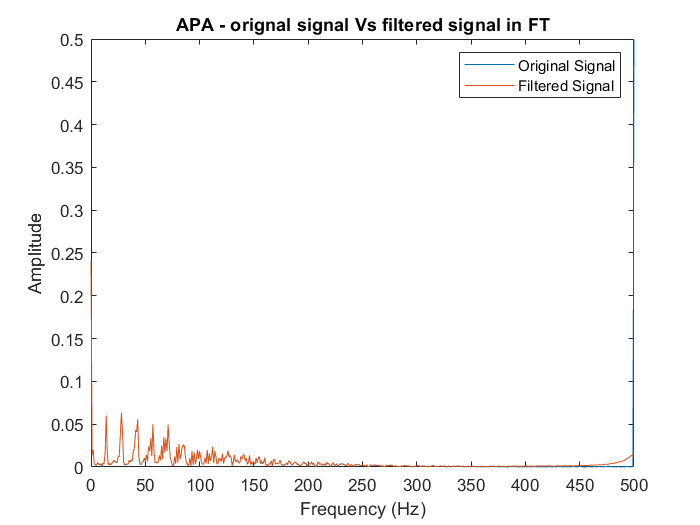

apa_fft = fft(e_apa);               % Perform the FFT
apa_fft_magnitude = abs(fftshift(apa_fft)) / N; 

figure;
plot(frequencies, [noisy_signal_fft_magnitude, apa_fft_magnitude]);
title("APA - orignal signal Vs filtered signal in FT")
legend('Original Signal',  'Filtered Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0,500])

calculate statistics

apa_SNR = calculate_SNR(signal, e_apa);
apa_PRD = calculate_PRD(signal, e_apa);
apa_MSE = calculate_MSE(signal, e_apa);
disp(['apa_SNR = ', num2str(apa_SNR)]);

apa_SNR = -12.8035


disp(['apa_PDR = ', num2str(apa_PRD)]);

apa_PDR = 22.8994


disp(['apa_MSE = ', num2str(apa_MSE)]);

apa_MSE = 0.0077225
